# Gaussian Process Regression Tutorial

By Salvador Gomez and Tanner Harms

On March 21, 2023 for the McKeon Lab group meeting.

## What is Gaussian Process Regression?

Gaussian Process Regression (GPR) represents the use of kernels for regressing a Gaussian process from data.  There is a lot packed into that statement...  To get a better grasp of what is going on in GPR, we will look at three key aspects: 

- Regression

- Gaussian Processes

- Kernel functions and their usefulness to regression problems 

This tutorial will only scratch the surface on GPR and its applications.  If you want to go into more depth, here are some suggested resources.

- Some link

- Another link

- And more links

Let's jump right in with some regression examples!

### Reminder about linear regression

A fundamental procedure in statistics is building models of phenomena from data.  Some of my favorite quotes about models (of all kinds) are attributed to the statistician George Box:

*"All models are wrong, but some are useful."*

*"Since all models are wrong, the scientist must be alert to what is importantly wrong.  It is inappropriate to be concerned about mice when there are tigers abroad."*

In using the appropriate data to examine a phenomenon, we hope to identify useful trends through the process of regression.  Mathematically, regression is often expressed as


$$Y_i = f(X_i,\beta) + e_i$$


where $(X_i, Y_i)$ are tuples containing the dependent variable and independent variables respectively, $\beta$ is a vector of unknown parameters to be estimated,$f(X_i, \beta)$ is a mapping of the independent variables and parameters to the dependent variable and $e_i$ are errors associated with the data points.  The task of regression is to use the data $(X_i, Y_i)$ to identify $\beta$ by minimizing $e_i$.

In the case of a linear regression, we would use the form


$$Y_i = \beta_0 + \beta_1X_i+e_i$$


Let's do an example in honor of George Box.

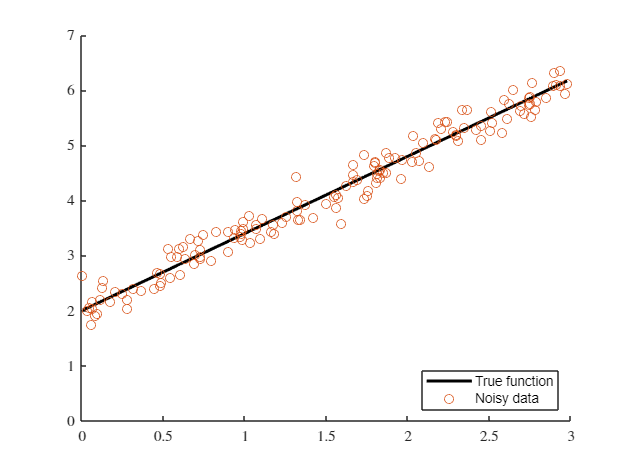

% Let's make a true function that we will sample from.  It will depend on
% betas and the independent variables with noise added.  
b0_true = 2;
b1_true = 1.4;
fun = @(b0, b1, X, sigma) b0 + b1*X + normrnd(0,sigma,size(X));

% Now, let's generate some data.  
N = 150;                      % Number of data points
Tigers = sort(3*rand([N,1])); % Uniform random from 0 to 3 
Mice = 0.2;                   % standard deviation for normal random noise added
HowConcernedIAm       = fun(b0_true, b1_true, Tigers, Mice);  % function with noise
HowConcernedIShouldBe = fun(b0_true, b1_true, Tigers, 0);     % function with no noise

% Plot the data
figure(); hold on; xlim([0,3]); ylim([0,7])
plot(Tigers, HowConcernedIShouldBe, 'k', 'linewidth',2)
scatter(Tigers, HowConcernedIAm)
legend('True function','Noisy data','location','southeast')

Now that we have a function in place, we can do regression to estimate the model.  This is accomplished by minimizing the error term in a least squares sense.  Skipping a lot of steps (see [Ordinary least squares - Wikipedia](https://en.wikipedia.org/wiki/Ordinary_least_squares) for details), you can use the *normal equations *to estimate $\beta$.


$$\hat{\beta} = (\mathbf{X}^\top \mathbf{X})^{-1} \mathbf{X}^\top \mathbf{Y}$$


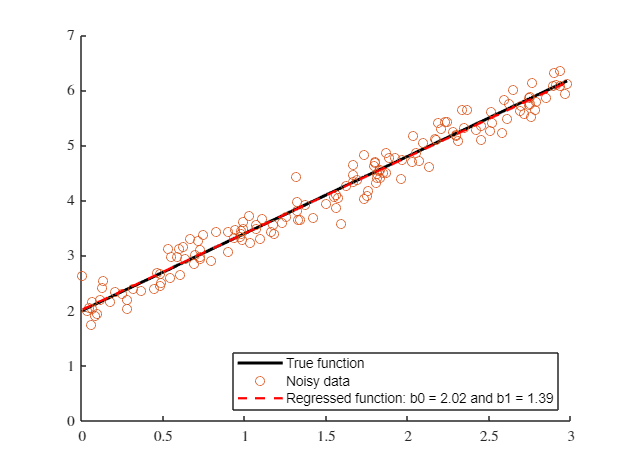

% Let's turn our data into an array.  For the bias term (b0) we say X0 = 1.
X = [ones(size(Tigers)), Tigers];
Y = HowConcernedIAm;

% Let's regress!
b_hat = pinv(X)*Y;

% and plot our new results onto the graph.  
regressed_fun = fun(b_hat(1), b_hat(2), Tigers, 0);
plot(Tigers, regressed_fun, '--r', 'linewidth',1.5)
leg = ['Regressed function: b0 = ',num2str(round(b_hat(1),2)),' and b1 = ',num2str(round(b_hat(2),2))];
legend('True function','Noisy data',leg,'location','southeast')

As we see, the regressed function matrches very closely!  However, if we didnt know the form of our model, then we would likely get far worse results.  For example, if we attempted to fit a linear model to data that is actually quadratic, then we would surely get bad results.  

This type of regression is known as parametric regression--we attempt to learn the parameters $\beta$ that are associated with a model family that we expect to see (linear in this case).  Gaussian process regression is a form of non-parametric models, which seeks to fit a general function that describes the expected value of the dependent variable given the independent variable set.  In math-talk, we are trying to solve for $m(x)$ in:


$$\mathbb{E}[Y|X=x]=m(x)$$


In the case of GPR, $m(x)$ is a specific type of function known as a Gaussian process.  We will cover those next.  

### Gaussian Processes

A Gaussian process is a *stochastic process* where each collection of the random values that it generates and all linear combinations thereof are distributed according to a multivariate normal distribution.  **For GP and GPR, the dimension of the multivariate distribution is the size of the state space that regression is occurring over.**  

Let's take a look at a quick example of an uncorrelated gaussian process.  

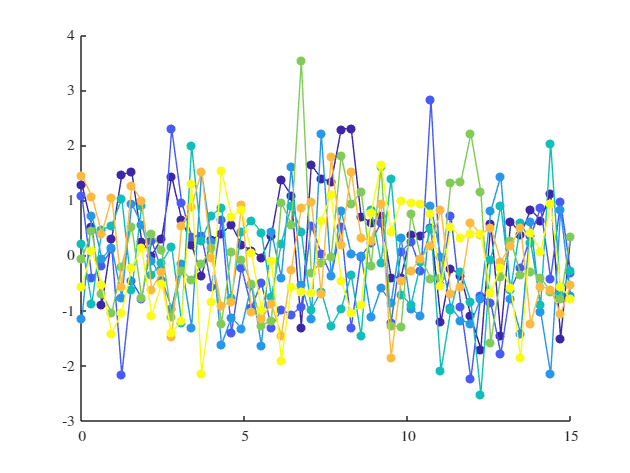

% Select values for the variables:
test_points = 50;
n_samples = 7;
domain = 15;
Xtest = linspace(0,domain,test_points)';

% In this case, we will generate (test_points)-variate normal distributions
% using the identity matrix as the covariance.  This essentially states
% that the points on the state-space are uncorrelated.  
mu = zeros([1,test_points]);            % Zero mean
cov = eye(test_points);                 % Uncorrelated
samples = mvnrnd(mu, cov, n_samples);

% Plot the results
col = parula(n_samples);
figure(); hold on
for i=1:n_samples
  plot(Xtest, samples(i,:), 'color', col(i,:))
  scatter(Xtest, samples(i,:), 'filled', 'MarkerFaceColor', col(i,:))
end

Because each of the test points is uncorrelated with all of the others, the result above appears to be random noise--although, a brief inspection verifies that the data is normally distributed about the mean with unit standard deviation.  By defining covariance matrix in a smart way, we can enforce certain behavior in our random variables.  

The function that we use to design our covariance matrix is called the **kernel function**, and it is defined as

$k(x,x') = f(x, x', p)$,

where $p$ are parameters that influence the kernel function's behavior.  Using the kernel function, the covariance (or kernel) matrix is defined according to


$$K_{ij} = k(x_i, x_j)$$


As we shall see later in the tutorial, the choice of kernel function is extrememly important to the character of the regressions that are done.  However, it is quite common to start with a Gaussian (aka. radial basis function or squared-exponential) kernel.  This is defined according to the relation

$k_{SE} (x,x') = \sigma^2 \exp\left(-\frac{(x-x')^2}{2l^2}\right)$,

where $l$ is a lengthscale that determins the wavelength of the output and $\sigma^2$ is the variance of the output.  We can demonstrate this again in the code:

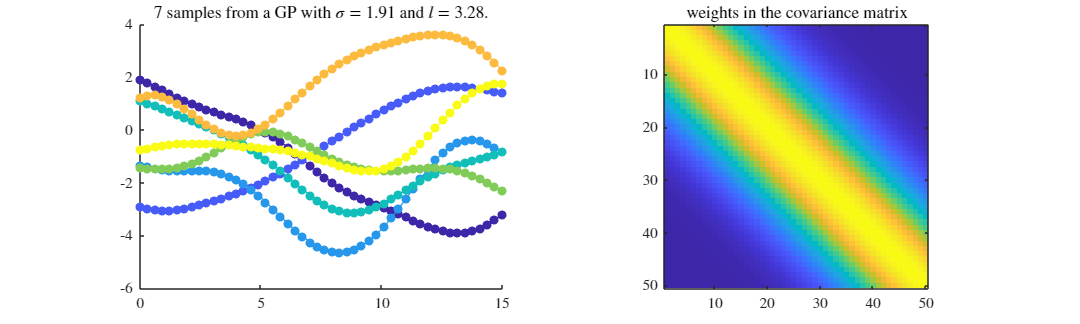

% First, let's define the gaussian kernel function.  We will use the same
% environment parameters from the previous code block.  
kernel_SE = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); 

% Let's use some variables to define our model parameters.
l     = 3.28;
sigma = 1.91;

% Now, to calculate the covariance matrix, we will compute the kernel function for
% every pair of data.
cov = zeros(test_points, test_points);
for i = 1:test_points
    for j = 1:test_points
        cov(i,j) = kernel_SE(Xtest(i),Xtest(j),sigma,l);
    end
end

% Now, we will re-plot the functions as before to see how kernelizing the
% covariance influences them.  
samples = mvnrnd(mu, cov, n_samples);

figure('units','inches','position',[1,1,10,3])
subplot(1,2,1); hold on   % Plot the samples
for i=1:n_samples
  plot(Xtest, samples(i,:), 'color', col(i,:))
  scatter(Xtest, samples(i,:), 'filled', 'MarkerFaceColor', col(i,:))
end
title([num2str(n_samples),' samples from a GP with $\sigma=', num2str(sigma), '$ and $l=', num2str(l),'$.'],'interpreter','latex')

subplot(1,2,2)            % Plot the covariance matrix
imagesc(cov)
title('weights in the covariance matrix','interpreter','latex')
axis square

Now, the task of Gaussian process regression is to fit the mean and covariance using known data within the regression domain.  Referring back to the non-parametric regression remodel from a few sections ago, we are try to solve for some function 

$\mathbb{E}[Y|X=x]=m(x)$,

where

$m(x) = \mathcal{N}(Y|\mu, K)$.

In other words, the prior assumption of the regression is that it is a Gaussian process governed by mean $\mu$ and covariance $K$.  Therefore, in GPR it is the mean and covariance that are identified.  This is advantageous since, unlike the parametric model from before, we learn not just the most likely function, but an entire family of functions that fit the data.  We will have natural confidence intervals on the data which are determined by the regression.  Let's see how this is done.  

### Choice of Kernel Functions

- Discuss choices of the hyperparameters in RBF (the std, amplitude, and regularizer)

- Discuss Kernel function properties

- Discuss common Kernel functions (RBF, Matern, Periodic, etc.)

We can define a few common kernel functions below:

set(groot, 'defaultAxesTickLabelInterpreter','latex')
clear all; close all; clc; 
%kernel functions you can choose: 
    kernel_fun1 = @(x1,x2,s,l) s.^2.*(1 + sqrt(3)./l.*abs(x1-x2)).*exp(-sqrt(3)/l*abs(x1-x2)); %matern 3/2
    kernel_fun2 = @(x1,x2,s,l) s.^2.*(exp(-abs(x1-x2)./l)); %matern 1/2
    kernel_fun3 = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); %radial basis function
    kernel_fun4 = @(x1,x2,s,l) s.^2 + (x1 - l).*(x2 - l); %linear basis function
    kernel_fun5 = @(x1,x2,s,l,Np) s.^2.*exp(-sin(pi*abs(x1-x2)*Np).^2./(2*l.^2)); %periodic kernel (define Np, number of periods you expect) 
%note that you can define many more! 

Note that this list is not exhaustive, there are (infinitely) many more options for kernel functions as we'll see later. 

Making the parameter *l* in the RBF smaller makes points that are further apart less correlated and increased *l *makes points that are further apart more correlated. 

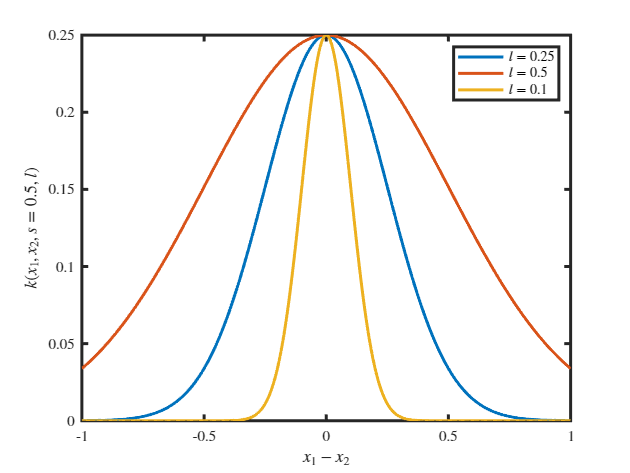

%now we'll show what happens when you vary the parameter l in the Radial Basis Function
x = linspace(-1,1,1000); 
s = .5; l1 = .25; l2 = .5; l3 = .1; 
figure(1)
    plot(x,kernel_fun3(x,0,s,l1),'LineWidth',2); hold on; 
    plot(x,kernel_fun3(x,0,s,l2),'LineWidth',2); hold on; 
    plot(x,kernel_fun3(x,0,s,l3),'LineWidth',2); hold on; 
    xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l)$'],'Interpreter','latex'); 
    legend({['$l = ',num2str(l1),'$'],['$l = ',num2str(l2),'$'],['$l = ',num2str(l3),'$']},'Interpreter','latex'); 
    set(gca,'linewidth',2); hold off; 

The Matern kernels adds *pointyness* to the radial basis function. This allows them to approximate functions that have sharp features without having to change the value of *l. *This *pointyness *increases the correlation of points that are close together while maintaining the correlation of the points that are further apart. You can think of this as having the benefits of a large *l *in getting global information (points far apart) while having the benefits of a small *l *in weighing local information (points close together). 

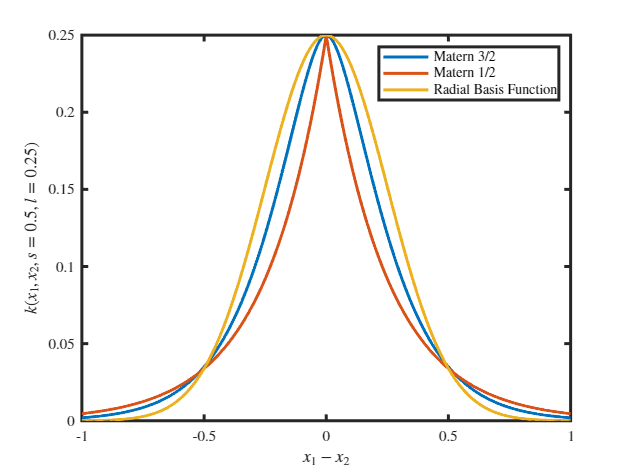

%plotting the kernel functions: 
x = linspace(-1,1,1000); 
s = .5; l = .25;
figure(1)
    plot(x,kernel_fun1(x,0,s,l),'LineWidth',2); hold on; 
    plot(x,kernel_fun2(x,0,s,l),'LineWidth',2); hold on; 
    plot(x,kernel_fun3(x,0,s,l),'LineWidth',2); hold on; 
    xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l = ',num2str(l),')$'],'Interpreter','latex'); 
    legend({'Matern $3/2$','Matern $1/2$','Radial Basis Function'},'Interpreter','latex'); 
    set(gca,'linewidth',2); hold off; 

The periodic kernel is useful when your signal has known periodicity (Np). 

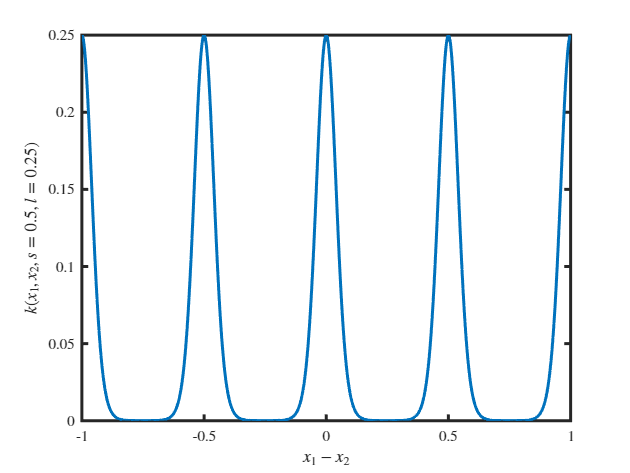

    %plotting the kernel functions: 
x = linspace(-1,1,1000); 
s = .5; l = .25;
figure(1)
    plot(x,kernel_fun5(x,0,s,l,2),'LineWidth',2); hold on; 
    xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l = ',num2str(l),')$'],'Interpreter','latex'); 
    set(gca,'linewidth',2); hold off; 

If these kernel functions do not suffice, you can build your own kernel functions by multiplying kernel functions together, adding them together, etc. 

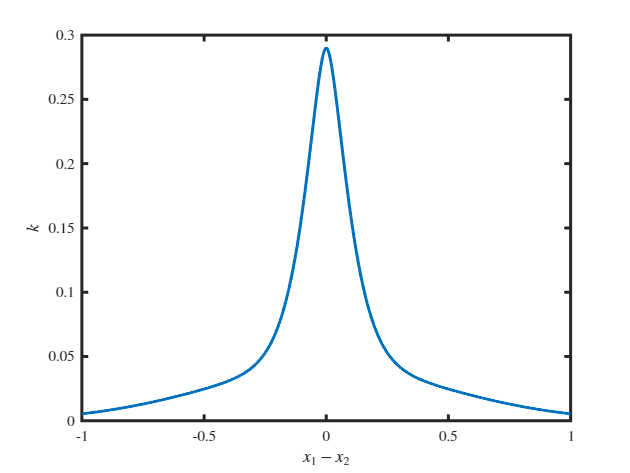

%example: 
    k_add = @(x1,x2,s,l,p,q) kernel_fun1(x1,x2,s,l) + kernel_fun3(x1,x2,p,q);
        plot(x,k_add(x,0,.5,.1,.2,.5),'LineWidth',2)
        xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k$'],'Interpreter','latex'); 
        set(gca,'linewidth',2); hold off; 

    %create your own kernels: 
    

## Kernel functions in practice: 

For the given parameters, the RBF does a lot better at approximating the sinusoidal input. However, when the function has an absolute value the Matern kernel does a better job at approximating the function. 

clear x_data y_data m_data
f          = @(x) .4*sin(5*pi*x) + 0*abs(5*(x-.5)); %function we want to model 
ftrue      = f(x);
x          = linspace(0,1,100)'; %points we'll use
rng(1)%seed we'll use
ii         = randperm(length(x))'; Num_Samples = 15; 
s = 1; l = .2; i = 10^-3;  %in practice, a robust code optimizes the choice os s and l and i 
figure()
tiledlayout(1,2,'TileSpacing','none','Padding',"compact");
nexttile
    %get data for the GPR:
    x0                     = x(ii(1:Num_Samples,1));
    eval                   = f(x0); %evaluate at sample point
    x_data                 = x0; 
    y_data                 = (eval); 
    m_data                 = [y_data];
    plot(x,ftrue,'LineWidth',2.5,'color','k'); ylim1 = ylim; hold on; %plot the actual data
    [mean_m, cov_m, var_m] = plot_results(x_data,m_data,x,s,l,i,kernel_fun1,0); %compute the GPR and plot
    xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex'); ylim(ylim1)
    legend('Matern 3/2','interpreter','latex')
    set(gca,'LineWidth',2,'FontSize',20)
nexttile
    %get data for the GPR:
    x0                     = x(ii(1:Num_Samples));
    eval                   = f(x0); %evaluate at sample point
    x_data                 = x0; 
    y_data                 = (eval); 
    m_data                 = [y_data];
    plot(x,ftrue,'LineWidth',2.5,'color','k'); ylim1 = ylim; hold on; %plot the actual data
    [mean_m, cov_m, var_m] = plot_results(x_data,m_data,x,s,l,i,kernel_fun3,0); %compute the GPR and plot
    xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex'); ylim(ylim1)
    set(gca,'LineWidth',2,'FontSize',20)
    legend('RBF','interpreter','latex')
    set(gcf,'position',[100,100,1000,400])

function [mean_m, cov_m, var_m] = plot_results(x_data,y_data,x,s,l,i,kernel_fun,Np)
%x_data is x locations of samples points, y_data is measurements at sampled points
%x is the data you wish to interpolate onto
%i is the regularizer
%if Np = 0 we are NOT using the periodic kernel. If Np > 0 it is number of
%periods expected in signal
%kernel_fun is the kernel function you want to use, takes in x1 and x2 as arguments
%Does the GPR and plots 
    if Np == 0
        %change nothing
    else
        kernel_fun = @(x1,x2,s,l) kernel_fun(x1,x2,s,l,Np); 
    end
    [mean_m, cov_m, var_m] = GPR(x_data,y_data(1:length(x_data),:),x,s,l,i,kernel_fun);
    std_m = sqrt(abs(real(var_m))); 
    x2 = [x,flip(x)];
    for ind1 = 1:5
        ind = 5-ind1+1;
        top = mean_m + ind*std_m; 
        bot = mean_m - ind*std_m; 
        inb = ([top;flip(bot)]);
        fill(x2(:),inb(:),[0.5569    0.5686    0.5608],'FaceAlpha',ind1*.05,'EdgeColor','none'); hold on;
    end
    hold on;
    colors = [0.8941    0.1020    0.1098;0.2157    0.4941    0.7216;0.3020    0.6863    0.2902;0.5961    0.3059    0.6392];%cbrewer('qual','Set1',4);%cbrewer('qual','Set1',4); 
%plotting:    
    plot(x,(mean_m),'LineWidth',1.5,'Color',colors(1,:))
    hold on; 
    plot(x_data,(y_data(1:length(x_data))),'.','LineWidth',2,'MarkerSize',20,'Color',colors(2,:))
    plot(x_data(end),(y_data(length(x_data))),'+','LineWidth',2,'MarkerSize',8,'Color',colors(3,:))
    xlabel('$x$','Interpreter','latex'); 
    set(gca,'LineWidth',2,'FontSize',18)
end

function [mean_at_values, cov_at_values, var_at_values] = GPR(xdata,ydata,x,s,l,i,kernel_fun)
%set up the kernels
    K  = covariance_matrix(xdata,xdata,s,l,kernel_fun);
    %the second term models noise and helps regularize the inversion
    Kl = chol(K + i*diag(ones(length(xdata),1)));
    Kli= inv(Kl);
    Ks = covariance_matrix(x,xdata,s,l,kernel_fun);
    Kss= covariance_matrix(x,x,s,l,kernel_fun);
%get the mean
    %mean_at_values = Ks*Ki*ydata(:); 
    mean_at_values = Kli'*ydata(:);
    mean_at_values = Kli*mean_at_values;
    mean_at_values = Ks*mean_at_values; 
%get the covariance
    KsKli = Ks*Kli;
    %cov_at_values  = Kss - Ks*Ki*(Ks)'; cov_at_values = (cov_at_values + (cov_at_values)')/2 + 0*eps*eye(size(cov_at_values));
    cov_at_values  = Kss - KsKli*KsKli';  cov_at_values = (cov_at_values + (cov_at_values)')/2;
    var_at_values  = diag(cov_at_values); 
    mean_at_values = mean_at_values(1:length(x));
    cov_at_values  = cov_at_values(1:length(x)); 
    var_at_values  = var_at_values(1:length(x)); 
end

function cov_mat = covariance_matrix(x1,x2,s,l,kernel_fun)
%covariance matrix without derivative info
    cov_mat1 = zeros(length(x1),length(x2));
    for ind1 = 1:length(x1)
        for ind2 = 1:length(x2)
            cov_mat1(ind1,ind2) = kernel_fun(x1(ind1),x2(ind2),s,l);
        end
    end
    cov_mat = cov_mat1; 
end

## Bayesian Optimization for GPR

- Discuss why it's needed, where it's used, how it compares to other methods

- Discuss the algorithm

- Discuss choice of acquisition functions